# Workshop: Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

### 0. Setup

Ensure Python is installed and confirm the version with [`pyenv`](https://mathworks.com/help/matlab/ref/pyenv.html). 

We will provide the path to the correct executable for MATLAB Online.

%pyenv
% if ~exist("p","var")
%     p = pyenv("Version","/usr/bin/python3")   % for MATLAB Online
% end

*Note: you may need to restart MATLAB if you've already run pyenv and try to change the interpreter.*

*Note: Consider your directories and path needs - often we need to add our directories to both MATLAB and Python paths. *

## 1. Call Python Built-in Functions

Call Python functions using **py.** notation:

Test a simple function.

%% Write code here
py.math.sqrt(42)

ans = 6.4807

py.list({1,2,'a','b'})

ans =   Python list with values:

    [1.0, 2.0, 'a', 'b']

    Use string, double or cell function to convert to a MATLAB array.


Pass name=value arguments using similar syntax (beginning in release R2022a)

%% Write code here
py.textwrap.wrap("Hello World",width=int8(2))

ans =   Python list with values:

    ['He', 'll', 'o ', 'Wo', 'rl', 'd']

    Use string, double or cell function to convert to a MATLAB array.


*Hint: Consider default and expected data types*

### Exercise 1: Call a Built-in Python Function

Try out some more Python built-in functions below:

%% Write code here
py.help("list")

Help on class list in module builtins:

class list(object)
 |  list(iterable=(), /)
 |  
 |  Built-in mutable sequence.
 |  
 |  If no argument is given, the constructor creates a new empty list.
 |  The argument must be an iterable if specified.
 |  
 |  Methods defined here:
 |  
 |  __add__(self, value, /)
 |      Return self+value.
 |  
 |  __contains__(self, key, /)
 |      Return key in self.
 |  
 |  __delitem__(self, key, /)
 |      Delete self[key].
 |  
 |  __eq__(self, value, /)
 |      Return self==value.
 |  
 |  __ge__(self, value, /)
 |      Return self>=value.
 |  
 |  __getattribute__(self, name, /)
 |      Return getattr(self, name).
 |  
 |  __getitem__(...)
 |      x.__getitem__(y) <==> x[y]
 |  
 |  __gt__(self, value, /)
 |      Return self>value.
 |  
 |  __iadd__(self, value, /)
 |      Implement self+=value.
 |  
 |  __imul__(self, value, /)
 |      Implement self*=value.
 |  
 |  __init__(self, /, *args, **kwargs)
 |      Initialize self.  See help(type(self))

## 2. Call User Defined Python Code

There are several ways to call user-defined Python code from MATLAB, depending on how the code is prepared.

Use [`pyrun`](https://mathworks.com/help/matlab/ref/pyrun.html) to execute python statements and [`pyrunfile`](https://mathworks.com/help/matlab/ref/pyrunfile.html) to run a Python script file. 

### Run Python Script

First, examine the code then run the script using pyrunfile.

pyrunfile("weather_script.py")

Displaying temperature for: Boston
The temperature is 48.79


Capture outputs from the script.

t = pyrunfile("weather_script.py","t")

Displaying temperature for: Boston
The temperature is 10.57


t = 10.5700

### Exercise 2.1: Run Python Script

Modify `weather_script.py` line 21 to display info for a different city and call it from MATLAB.

%% Write code here



### Call Python Module

To call a module from MATLAB, we use this syntax

*Note: When you modify a module, you need to reload it for the changes to take effect. See the Appendix below for an example. *[*Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)*](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

### Call Weather Module

The `weather.py` module reads and parses current weather data from the web API by location: [https://openweathermap.org/api](https://openweathermap.org/api)

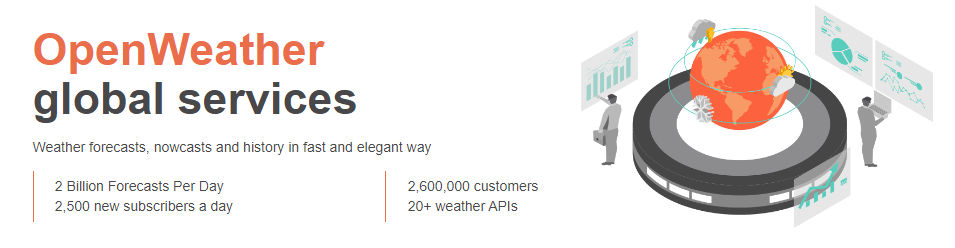

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location. Use code

%% Write code here
jsonData = py.weather.get_current_weather("Boston","US",apikey.Key)

Unable to resolve the name 'py.weather.get_current_weather'.

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

Extract the values from the dictionary. 

weatherData{"temp"}

### Exercise 2.2: What is the Forecast? 

Now, use the following syntax to call the `get_forecast` function from the weather module:

%% Write code here
jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData)

% Get the current time
forecastData{"current_time"}

Note the data types returned, which we will examine next.

## 3. Convert to MATLAB Data Types

Now we want to operate on this data in MATLAB, so the next step is to convert the data types as needed. There is a table in the doc with the data types listed: [**MATLAB to Python Data Type Mapping**](https://uk.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html)

### Convert Weather Data

Now, we'll get back to converting our weather data which is a dictionary containing mixed data types. 

weatherData

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

Convert the Python types within the struct to the desired MATLAB data types.

data.pressure = double(data.pressure);
data.city = string(data.city)

### Exercise 3: Convert Weather Data

Convert remaining Python types to MATLAB types.

%% Write code here


Perform the remaining conversions and create a table using the function provided to prep for machine learning.

currentData = prepData(weatherData)

## 4. Predict Air Quality

A machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file. 

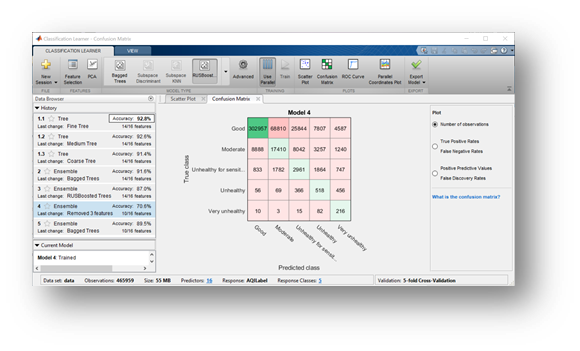

Use the model to predict the air quality for the new weather data.

load airQualModel 
airQual = predict(model,currentData)

### Exercise 4: Predict Air Quality

Test the prediction code in MATLAB for different locations. The function `predictAirQual.m `captures the previous steps (to be tested and later called from Python)

city = "Boston";
jsonData = py.weather.get_current_weather(city,"US",apikey.Key);
weatherData = py.weather.parse_current_json(jsonData)
predictAirQual(weatherData)

## 5. Bonus: Manage Arrays of Weather Forecast Data

Now let's look at the weather forecast for this week!

city = "Detroit";
jsonData = py.weather.get_forecast(city,"US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

It can be converted to a matrix of doubles:

tempForecast = double(forecast.temp)         

Transform **timestamp list** from Python in **MATLAB datetime**:

T = string(forecast.current_time)

Convert T in datetime and plot

time = datetime(T)
plot(time,tempForecast)
xtickangle(45)
title("Temperature Forecast")
ylabel("Temperature (\circF)")

### Bonus: Preprocess Data Using Live Editor Tasks

Go to the Tasks buttom in the Live Editor toolstrip and select Create Plot

%% Insert plot task here


Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'});

% Retime timetable
newTimetable = retime(foreTemp,"regular","makima","TimeStep",hours(3))
plot(foreTemp.Time,foreTemp.Temperature); hold on
plot(newTimetable.Time,newTimetable.Temperature); hold off
legend("Data","Resampled Data")
title("Temperature Forecast")
ylabel("Temperature (\circF)")

Select different trend removal parameters and examine the results.

% Remove trend from data
detrendedData = detrend(tempForecast,2);

% Display results
clf
plot(tempForecast,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(detrendedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(tempForecast-detrendedData,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

There are a number of Live Editor Tasks you can add to this script to continue to clean the data (smooth, remove outliers, etc.). Try these out for yourself!

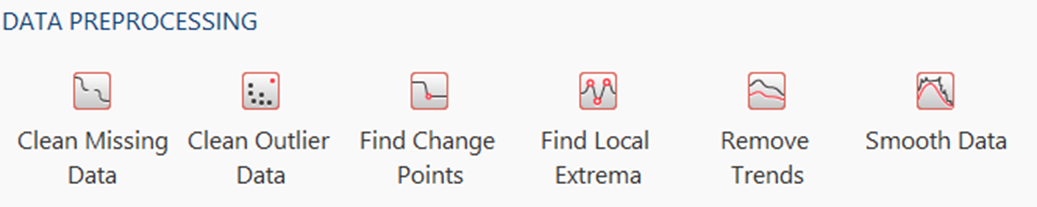

## Part 3: Call MATLAB Prediction Code from Python

Call a function capturing these steps and the correct data conversions to be called in the Python environment to predict the air quality. See `predictAirQual.m`

% edit("predictAirQual.m")

Next, we will call this code from Python using the [MATLAB Engine API for Python](https://mathworks.com/help/matlab/matlab-engine-for-python.html). See `CallMATLABfromPython.ipynb `for the next steps. 

## Appendix

[Cheatsheets for Using MATLAB with Python](https://mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html) 

Documentation and troubleshooting info: [Calling Python from MATLAB](https://mathworks.com/help/matlab/call-python-libraries.html)

Reloading Python modules

Reload *weather.py *after modifications:

% clear classes
% mod = py.importlib.import_module('weather'); 
% py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

*Copyright 2022 - 2023 The MathWorks, Inc.*